# Hyperspectral Unmixing on TI and TE dataset with MATLAB

This notebood demonstrates how to perform unmixing and visualize hyperspectral data using MATLAB. We will load reflectance data, visualize selected spectral bands, and compute the abundance of materials, with endmembers which is also utilized for forming TI and TE datasets , using the Least Squares (LS), the Least Squares Orthogonal Subspace Projection (LSOSP), the Non-negative Constrained Least Squares (NCLS) methods, and the Fully Constrained Least Squares (FCLS).

## 1. Load and Prepare Data

The first step is to load the reflectance data and prepare it for processing. Downloads the dataset by cloning the tite GitHub repository to the local environment. The dataset is stored in a folder named tite. Then, we can load the variables from the tite_reflectance.mat file into the MATLAB environment.

% Download Dataset
if ~exist("./tite/tite_reflectance.mat")
    gitclone("https://github.com/Brunoxue/tite.git");
end

% Load Dataset
load("tite/tite_reflectance.mat");
hsi=double(TI2);
M=[double(minerals),background];

The variable **hsi** represents the hyperspectral image cube, and the variable **M** contains reference spectra for minerals and background material.

## 2. Visualizing a Specific Band

Next, we will display a selected band (100th band in this case) of the hyperspectral image and plot the reference spectra. The left panel contains the visualization of the reflectance intensity at the 100th spectral band, and the right panel shows the intensity curves of the materials (minerals and background) across all spectral bands.

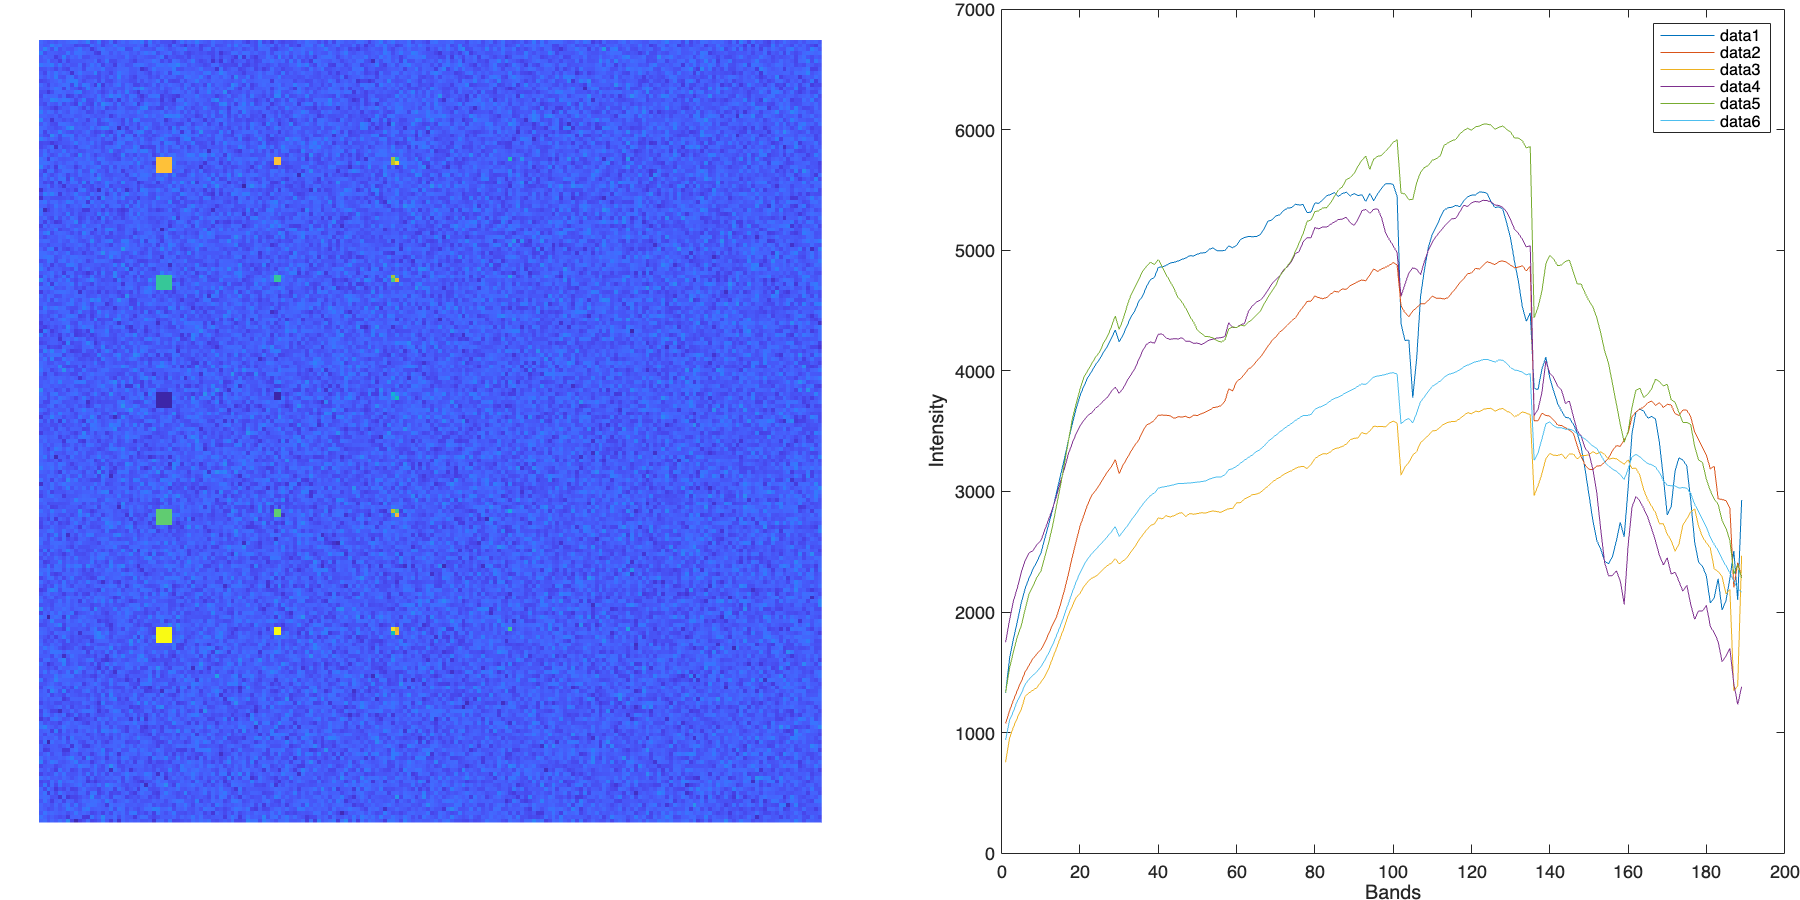

figure("Units","pixels","Position",[1,1,1000,500]);
tiledlayout(1,2,"Padding","tight");

% First tile: Visualize the 100th band of the hyperspectral image
nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;

% Second tile: Plot the spectral intensity across bands
nexttile,plot(M);
    legend;
xlabel("Bands");
ylabel("Intensity");

## 3. Linear Unmixing using Least Squares (LS)

In this block, we apply the Least Squares (LS) method to estimate the abundance maps of the materials in the testing hyperspectral image. The output variable abundanceLS contains abundance maps for each of the 6 materials, and each panel in the figure shows the abundance spatial distribution of one material (and background).

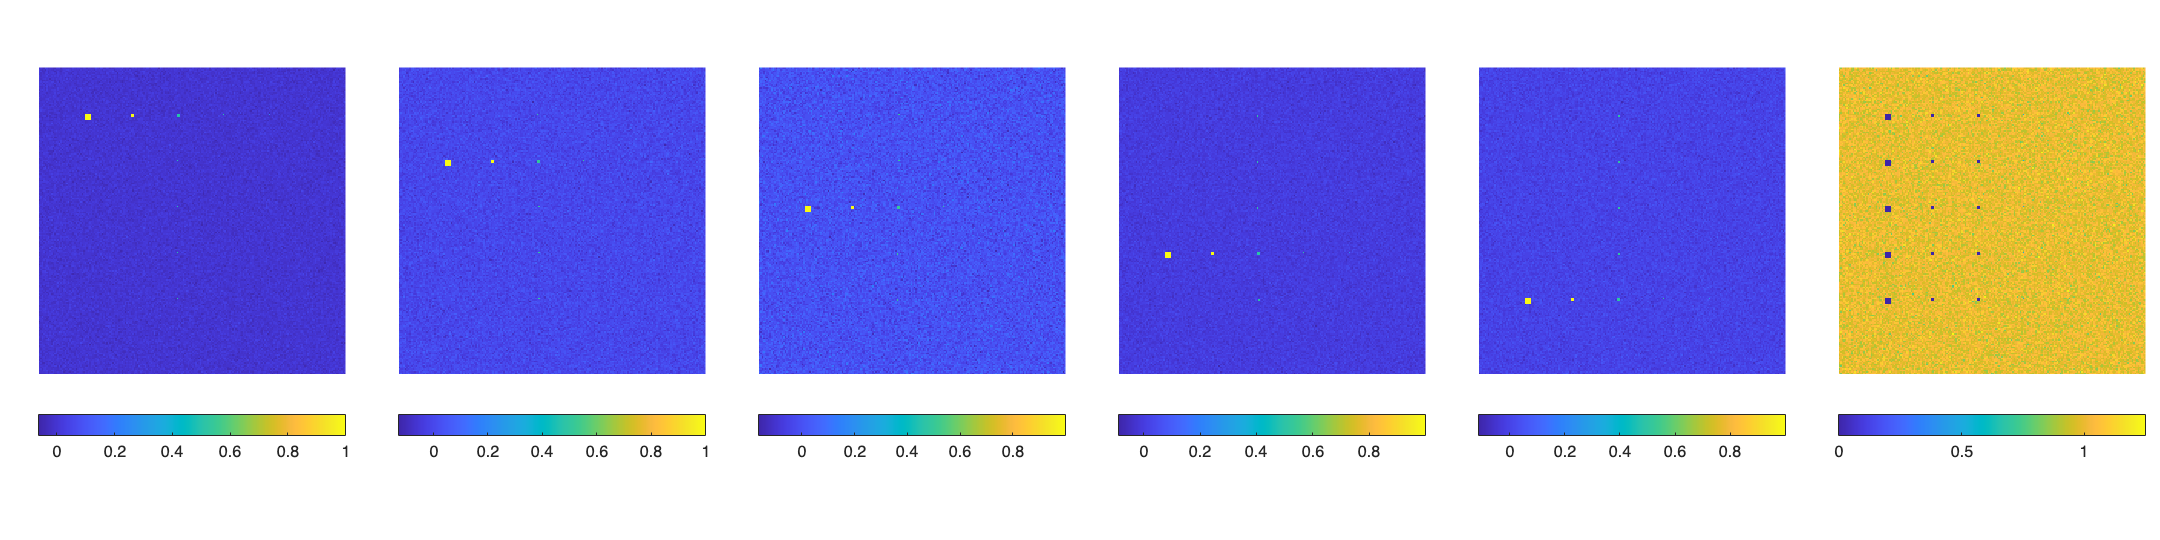

% LS
abundanceLS = LS(hsi, M);
figure("Units","pixels","Position",[1,1,1200,300]);
tiledlayout(1,6,"TileSpacing","tight","Padding","tight");
for idx = 1:6
    nexttile,imagesc(abundanceLS(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

## 4. Least Squares Orthogonal Subspace Projection (LSOSP)

The LSOSP method estimates the abundance of each material in the hyperspectral image while removing interference from other materials. This is done by projecting the data onto a subspace orthogonal to the spectra of all other undesired materials. The figure displays abundance maps for each of the 6 materials in separate subplots.

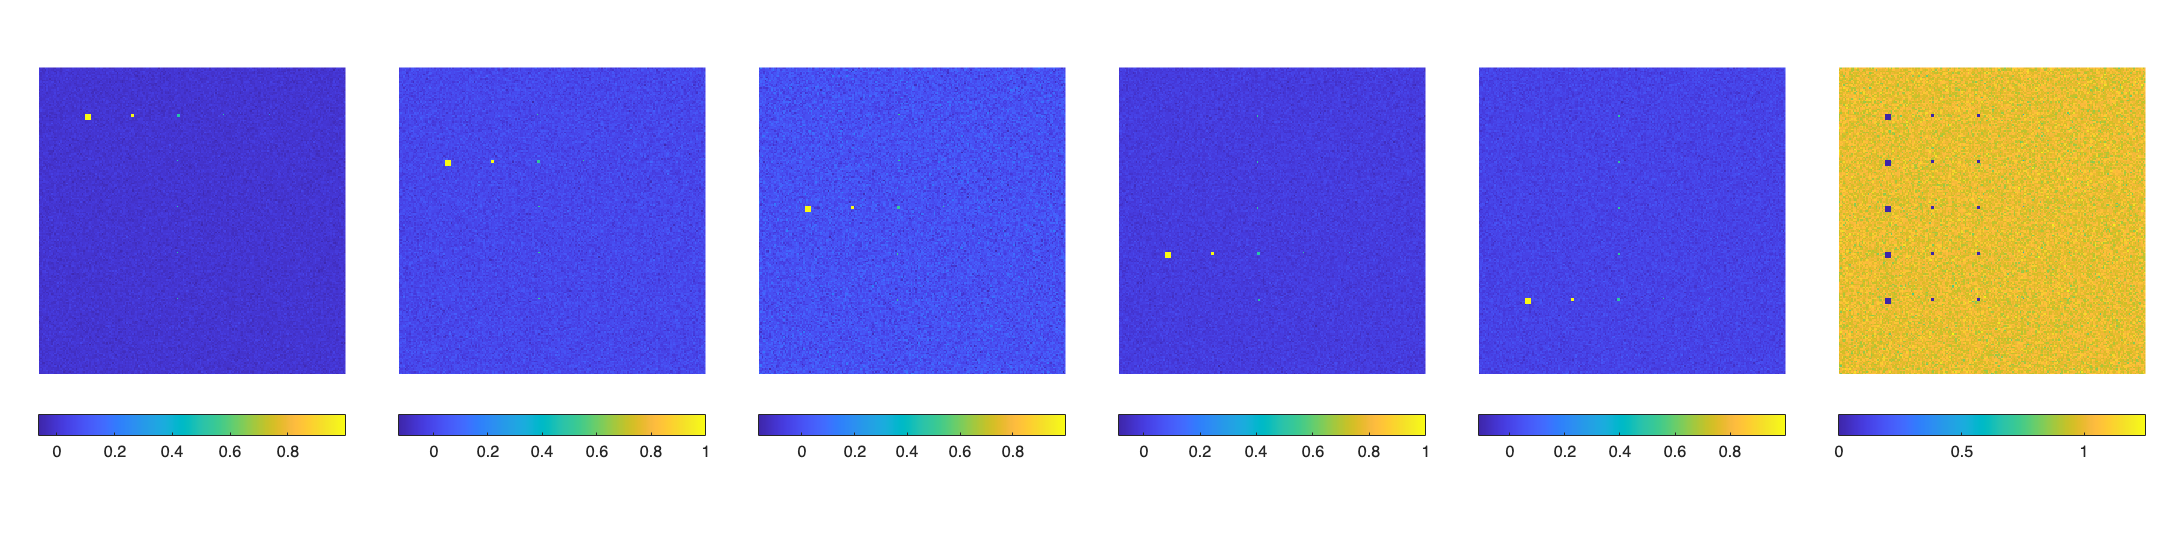

% LSOSP
figure("Units","pixels","Position",[1,1,1200,300]);
tiledlayout(1,6,"TileSpacing","tight","Padding","tight");
for idx = 1:6
    d=M(:,idx);
    U=M;
    U(:,idx)=[];
    abundanceLSOSP=LSOSP(hsi,d,U);
    nexttile,imagesc(abundanceLSOSP),axis off,axis image;
    colorbar southoutside;
end

## 5. Linear Unmixing using Non-negative Constrained Least Squares (NCLS)

Next, we use the NCLS method, which constrains the abundance values to be non-negative. Each subplot shows the abundance of materials in the scene as computed by the NCLS method.

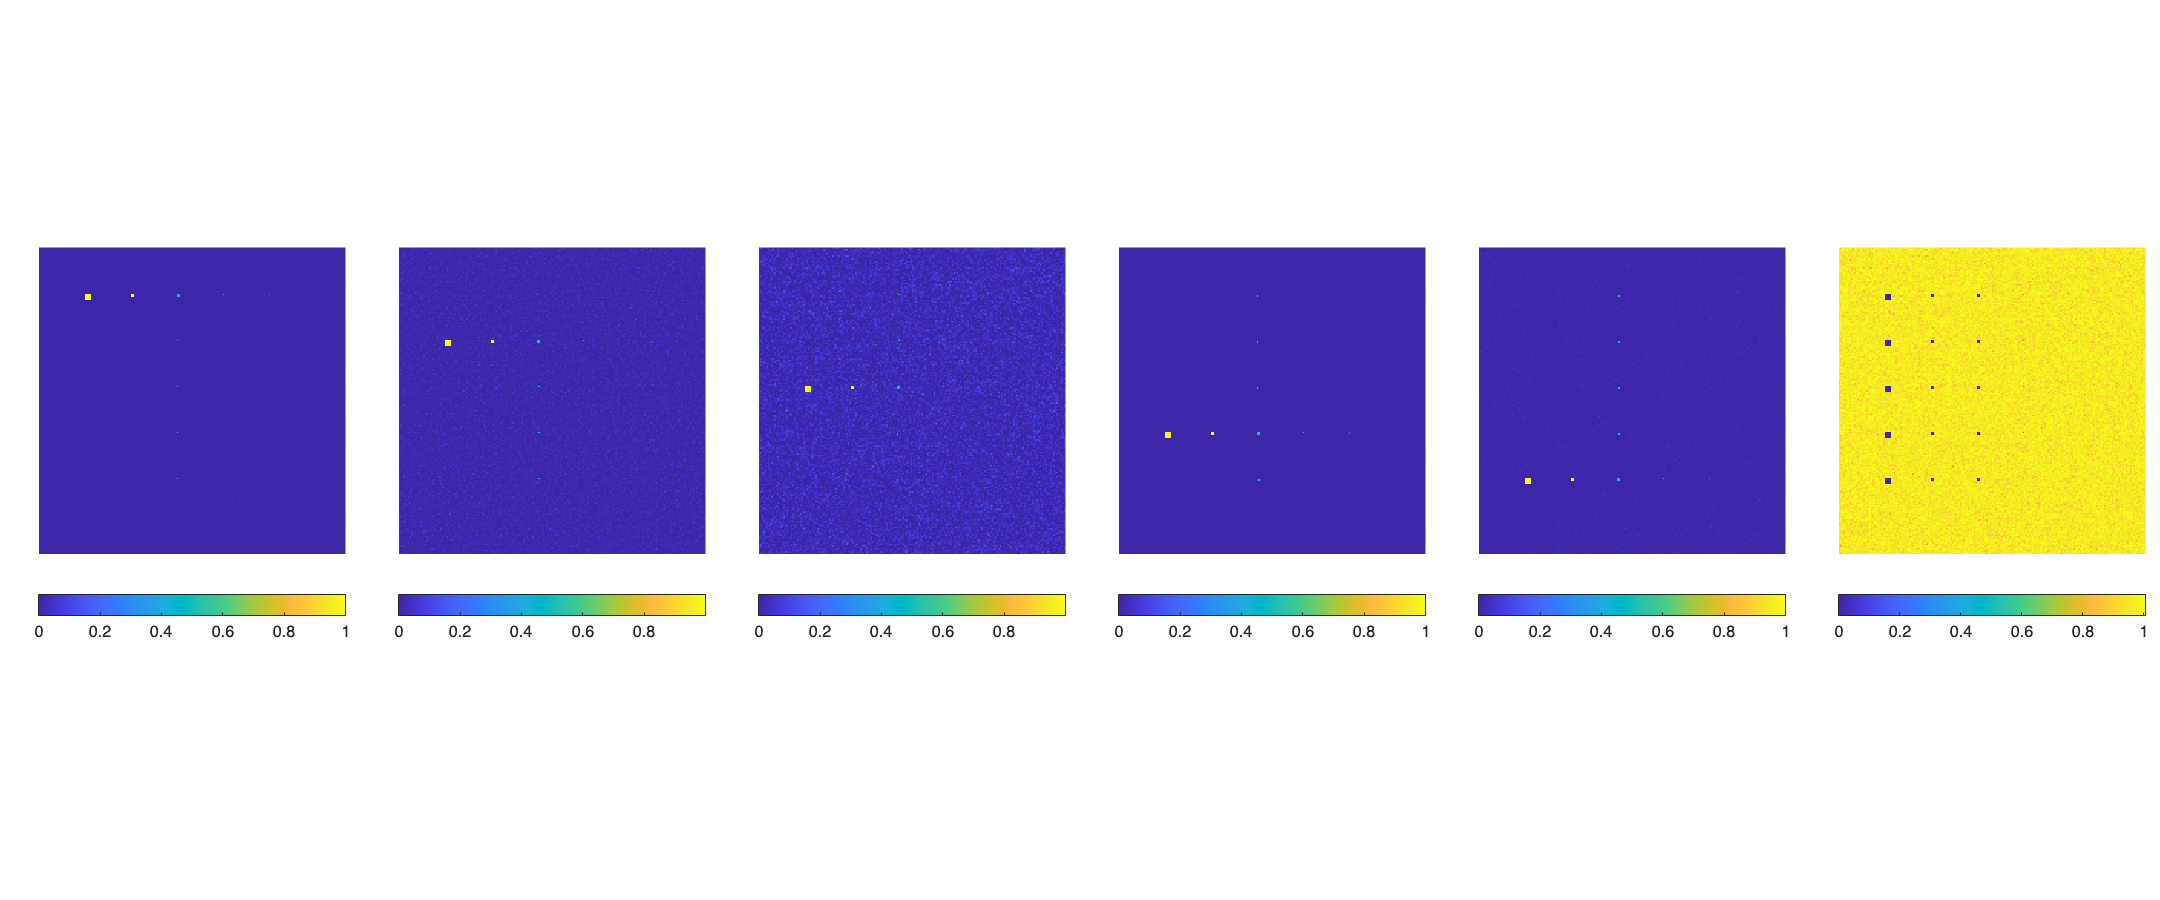

% NCLS
abundanceNCLS = NCLS(hsi, M);
figure("Units","pixels","Position",[1,1,1200,500]);
tiledlayout(1,6,"TileSpacing","tight","Padding","tight");
for idx = 1:6
    nexttile,imagesc(abundanceNCLS(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

## 6. Linear Unmixing using Fully Constrained Least Squares (FCLS)

The FCLS method follows two important constraints on the abundance estimates, which are non-negativity(same as the NCLS), and the sum-to-one (the abundance values across all materials must sum to one for each pixel, ensuring that the materials completely describe the pixel).

Each subplot represents the estimated abundance of a specific material, ensuring that the abundance follows non-negative and sum-to-one constraints.

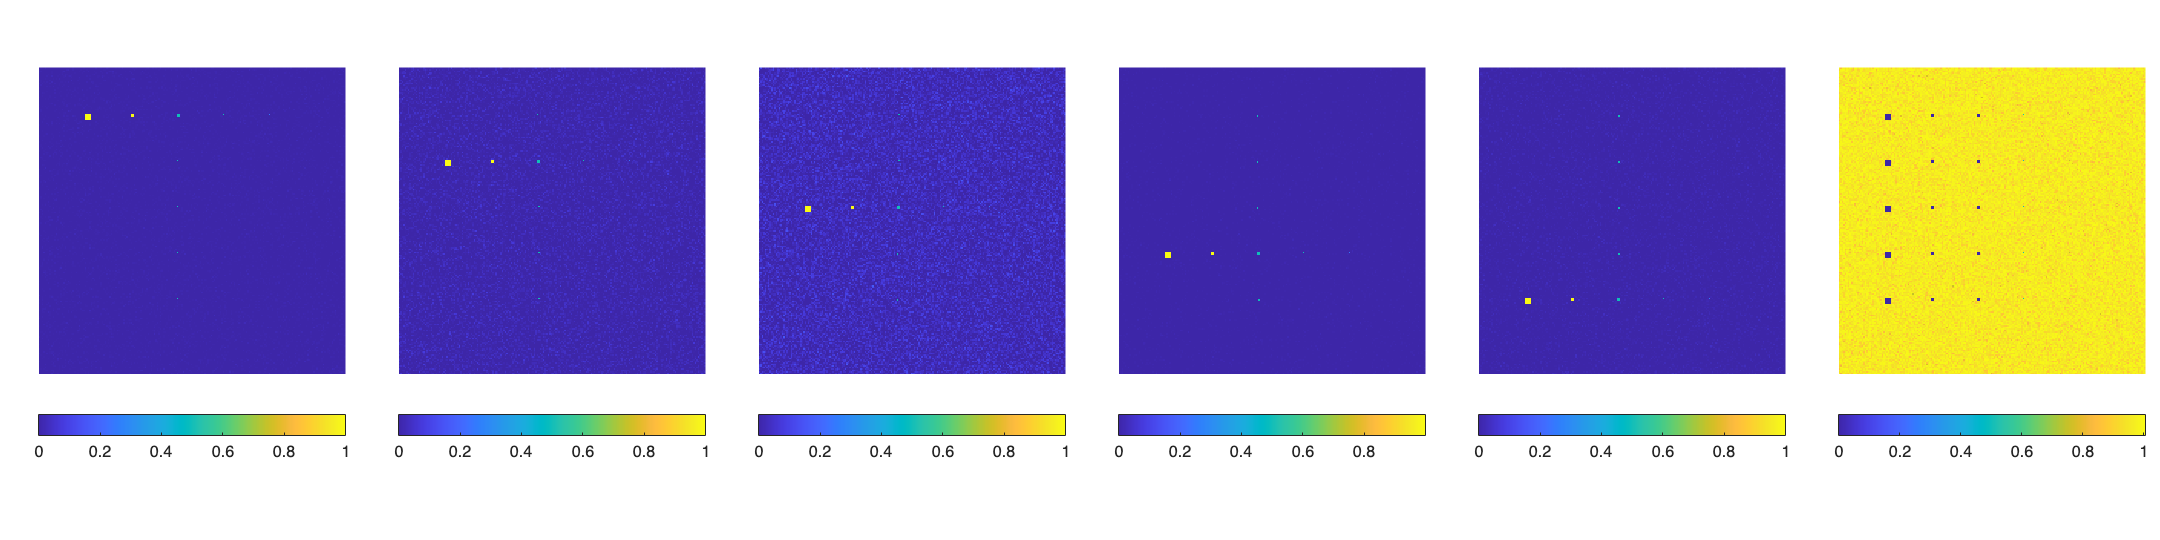

% FCLS
abundanceFCLS = FCLS(hsi, M);
figure("Units","pixels","Position",[1,1,1200,300]);
tiledlayout(1,6,"TileSpacing","tight","Padding","tight");
for idx = 1:6
    nexttile,imagesc(abundanceFCLS(:,:,idx)),axis off,axis image;
    colorbar southoutside;
end

## Functions for Above Tasks

% Subfunctions
function abundanceLS = LS(HSI, M)
    [x,y,L] = size(HSI);
    N=x*y;
    p=size(M,2);

    r=reshape(HSI,N,L);

    abundanceLS = pinv(M'*M)*M'*r';
    abundanceLS = reshape(abundanceLS',x,y,p);
end

function abundanceLSOSP = LSOSP(HSI, d, U)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    P_U_Per=eye(L)-U*pinv(U'*U)*U';

    lower = d'*P_U_Per*d;
    abundanceLSOSP = d'*P_U_Per*r'/lower;
    abundanceLSOSP = reshape(abundanceLSOSP,x,y);

end

function abundanceNCLS = NCLS(HSI,M)
    [x,y,L] = size(HSI);
    p=size(M,2);

    N=x*y;
    r=reshape(HSI,N,L)';

    options = optimset('TolX',1e-4,"Display","off");

    abundanceNCLS = zeros(N,p);
    for idx = 1:N
        abundanceNCLS(idx,:) = lsqnonneg(M,r(:,idx),options);
    end
    abundanceNCLS = reshape(abundanceNCLS,x,y,p);
end

function abundanceFCLS = FCLS(HSI,M)
    [x,y,L] = size(HSI);
    p=size(M,2);

    N=x*y;
    r=reshape(HSI,N,L)';

    M=[M;ones(1,p)];
    r=[r;ones(1,N)];

    options = optimset('TolX',1e-4,"Display","off");

    abundanceFCLS = zeros(N,p);
    for idx = 1:N
        abundanceFCLS(idx,:) = lsqnonneg(M,r(:,idx),options);
    end
    abundanceFCLS = reshape(abundanceFCLS,x,y,p);
end